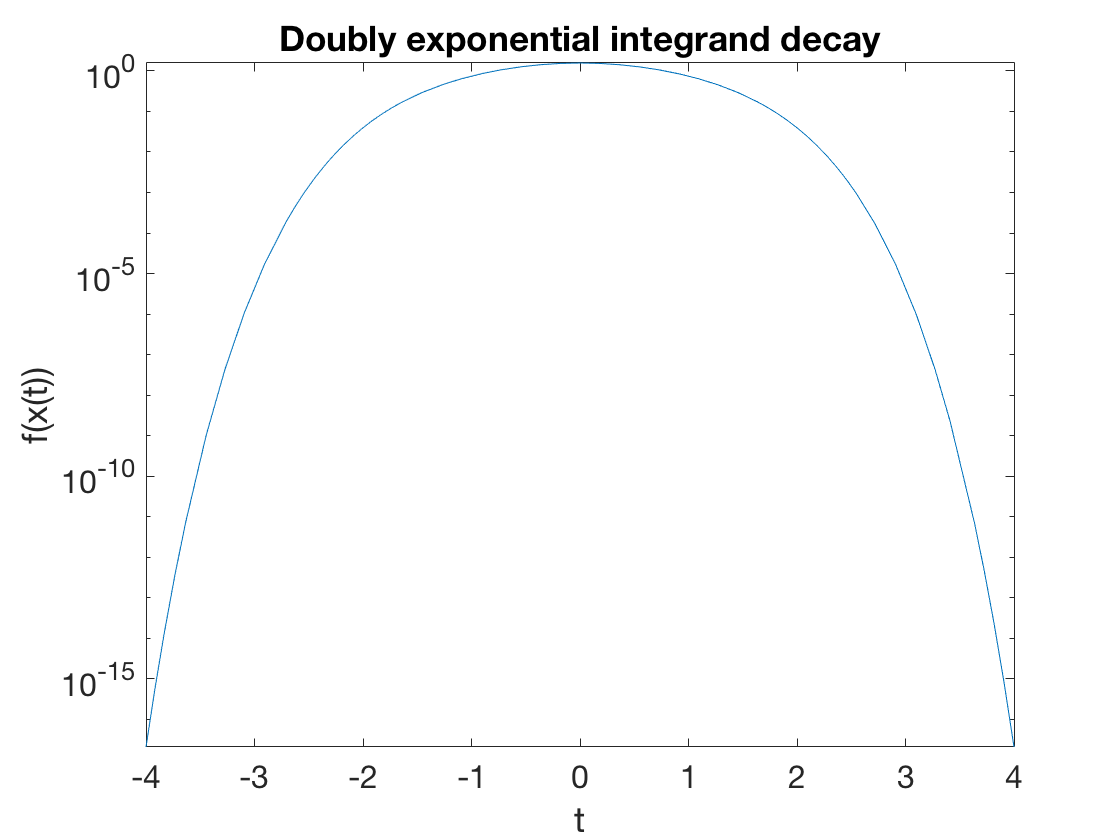

f = @(x) 1./(1+x.^2);
x = @(t) sinh(pi*sinh(t)/2);
chain = @(t) pi/2*cosh(t).*cosh(pi*sinh(t)/2);
integrand = @(t) f(x(t)).*chain(t);

fplot(integrand,[-4 4])
set(gca,'yscale','log') 
xlabel('t'), ylabel('f(x(t))')  % ignore this line
title('Doubly exponential integrand decay')  % ignore this line

This graph suggests that we may integrate $t$ from $-4$ to $4$ and capture all of the integrand values that are larger than machine epsilon.